% x'=4x+8t,  x(0)=3/2
f = @(t,x) 4*x+8*t;
tspan = [0,3];
x0 = 1.5;

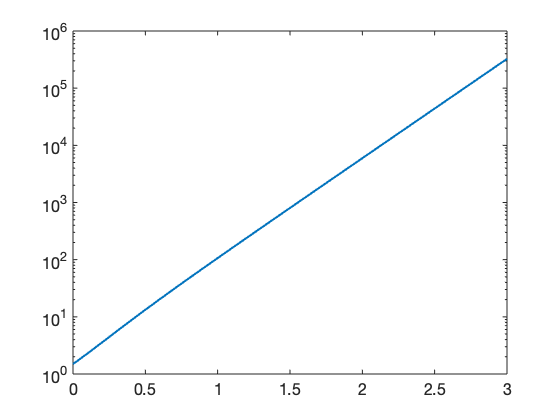

[t,x] = ode45(f,tspan,x0);
semilogy(t,x)

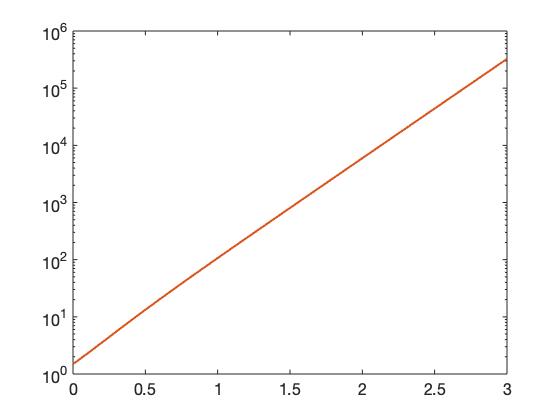

exact = @(t) 2*exp(4*t) - (4*t+1)/2;
hold on
semilogy(t,exact(t))

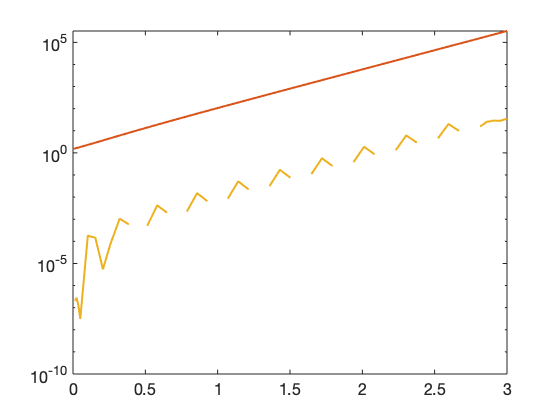

hold off

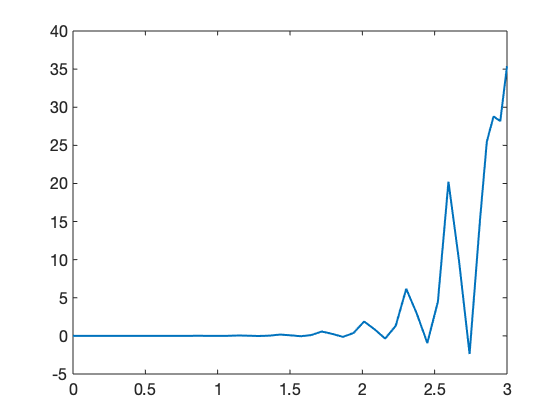

plot(t,x-exact(t))